# Hybrid dmss test

clear, close all

## Test empty hyDmss

emptySys= dmss()

emptySys =   dmss with properties:

                H: [1×1 hyCPN1]
                n: []
                m: []
                p: []
      outputIndex: [1×1 struct]
              nEq: []
        stateName: [0×0 string]
        stateUnit: [0×0 string]
    algebraicName: [0×0 string]
    algebraicUnit: [0×0 string]
        inputName: [0×0 string]
        inputUnit: [0×0 string]
               ts: []


## Test create hyDmss (numeric and symbolic!)

H = hyCPN1()

H =   hyCPN1 with properties:

      F: [1×1 struct]
    phi: [1×1 struct]
      R: 0


H.F.state = [0 0 1 0 0 0 0 0 0 1 0 0 0;...
    0 1 0 0 0 1 0 0 0 0 0 0 0;...
    0 0 0 0 0 0 0 0 0 0 1 0 0];
H.F.stateDerivative = [1 0 0 0 0 0 0 0 0 0 0 0 0;...
    0 0 0 1 0 0 0 0 0 0 0 0 0;...
    0 0 0 0 0 0 0 0 0 0 0 1 1];
H.F.algebraic = [0 0 0 0 0 0 1 0 0 0 0 0 0;...
    0 0 0 0 0 0 0 1 0 0 0 0 0];
H.F.boolean = [0 0 0 0 1 0 0 0 2 2 0 0 0];
H.F.input = [0 1 0 0 0 0 0 0 0 0 0 0 0;...
    0 0 1 0 0 0 0 0 0 0 0 0 0;...
    0 0 0 0 0 0 0 0 1 0 0 0 0];

H.phi.equality = [1 -0.13  0.13 0 0 0 0 0 0 0 0 0 0;...
    0 0 0 1 0 0 0 0 0 0 -1 0 0;...
    0 0 0 0 -1/1 1/1 0 0 0 0 15 0.5 0.5;...
    0 -1 0 0 0 0 1 0 0 0 0 0 0;...
    0 -1 0 0 0 0 1 0 0 0 0 0 0;...
    0 0 -1 0 0 0 0 1 0 0 0 0 0];
H.phi.inequality = [0 0 0 0 0 0 0 0 -1 1 0 0 0;...
    0 0 -1 0 0 0 0 1 0 0 0 0 0];

sys = dmss(H, 0);

At least one inequality is equal to an equation! The inequality has been reduced.
Reduced by 1 column(s) and 2 equation(s) with trivial Reduction due to duplications.



symEq = sys.symbolicEquations();
disp(symEq)

$$\left(\begin{array}{c} {\mathrm{xp}}_{1}-0.1300\,u_{1}\,x_{2}+0.1300\,u_{2}\,x_{1}=0\\ {\mathrm{xp}}_{2}-x_{3}=0\\ x_{2}+15\,x_{3}+{\mathrm{xp}}_{3}-z_{1}=0\\ y_{1}-u_{1}\,x_{2}=0\\ y_{2}-u_{2}\,x_{1}=0\\ x_{1}\,\left(2\,z_{1}-1\right)-u_{3}\,\left(2\,z_{1}-1\right)\leq 0 \end{array}\right)$$

## Continuous simulation

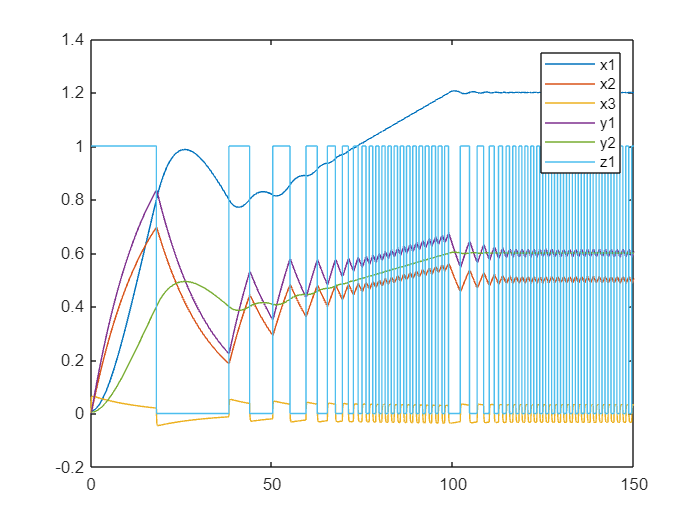

ut = 0:150;
x0 = [0.01; 0; 0];
u = [1.2, 0.5, 0.8] .* ones(size(ut))';
u(50:100,3) = u(50:100,3) + 0.4 * (1:length(u(50:100,3)))'/length(u(50:100,3));
u(101:end,3) = u(101:end,3) + 0.4;
opt = odeset('RelTol', 10.0^(-3),'AbsTol',10.0^(-3), 'MaxStep', 1, 'MaxOrder',1);
tic()
sim = dmsim(sys, x0, ut, u, opt);
timeC = toc();
plot(sim.tsim, [sim.x, sim.y])
hold on
plot(sim.zt, sim.z)
legend(["x1", "x2", "x3", "y1", "y2", "z1"])
hold off

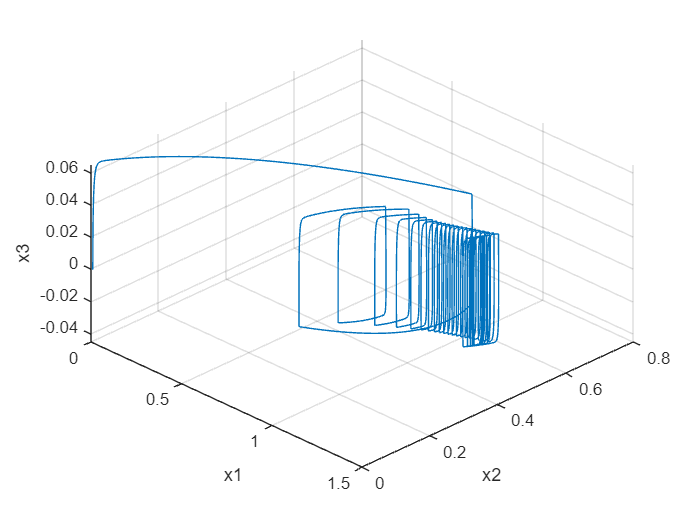

plot3(sim.x(:,1), sim.x(:,2), sim.x(:,3))
hold on
xlabel('x1')
ylabel('x2') 
zlabel('x3')
grid on
view([45 45])
hold off

## Test Jacobian (numeric and symbolic!)

% xp = [-2*10^-5; 0.3334; 0.3334]; 
% x = [0.8; 0.3332; 0.3332];
% y = [0.3999; 0.4];
% z = [0.33333];

xp = sym('xp',[sys.n,1]);
x = sym('x',[sys.n,1]);
y = sym('y', [sys.p,1]);
u = sym('u',[sys.m,1]);
z = sym('z',[sys.q,1]);

J = sys.jacobian(xp, x, u, y, z);
disp([J.equality.stateDerivative, J.equality.state, J.equality.algebraic, J.equality.input, J.equality.boolean])

$$\left(\begin{array}{cccccccccccc} 1 & 0 & 0 & 0.1300\,u_{2} & -0.1300\,u_{1} & 0 & 0.1300\,x_{1} & 0 & 0 & 0 & -0.1300\,x_{2} & 0\\ 0 & 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 1 & 15 & 0 & 0 & 0 & 0 & 0 & -1\\ 0 & 0 & 0 & 0 & -u_{1} & 0 & 0 & 0 & 1 & 0 & -x_{2} & 0\\ 0 & 0 & 0 & -u_{2} & 0 & 0 & -x_{1} & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

disp([J.inequality.stateDerivative, J.inequality.state, J.inequality.algebraic, J.inequality.input, J.inequality.boolean])

$$\left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 2\,z_{1}-1 & 0 & 0 & 0 & 1-2\,z_{1} & 0 & 0 & 0 & 2\,x_{1}-2\,u_{3} \end{array}\right)$$


%disp(double(subs([J.equality.derivative, J.equality.float, J.equality.input, J.equality.boolean], 'f1', 1)))
%disp(double(subs([J.inequality.derivative, J.inequality.float, J.inequality.input, J.inequality.boolean], 'f1',1)))

## Test sym2hyDmss -> poly2hyDmss -> str2hyDmss

disp(symEq)

$$\left(\begin{array}{c} {\mathrm{xp}}_{1}-0.1300\,u_{1}\,x_{2}+0.1300\,u_{2}\,x_{1}=0\\ {\mathrm{xp}}_{2}-x_{3}=0\\ x_{2}+15\,x_{3}+{\mathrm{xp}}_{3}-z_{1}=0\\ y_{1}-u_{1}\,x_{2}=0\\ y_{2}-u_{2}\,x_{1}=0\\ x_{1}\,\left(2\,z_{1}-1\right)-u_{3}\,\left(2\,z_{1}-1\right)\leq 0 \end{array}\right)$$

symsys = sym2dmss(symEq, 0);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


symSymEq = symsys.symbolicEquations();
disp(symSymEq)

$$\left(\begin{array}{c} 100\,{\mathrm{xp}}_{1}-13\,u_{1}\,x_{2}+13\,u_{2}\,x_{1}=0\\ {\mathrm{xp}}_{2}-x_{3}=0\\ x_{2}+15\,x_{3}+{\mathrm{xp}}_{3}-z_{1}=0\\ y_{1}-u_{1}\,x_{2}=0\\ y_{2}-u_{2}\,x_{1}=0\\ u_{3}-x_{1}-2\,u_{3}\,z_{1}+2\,x_{1}\,z_{1}\leq 0 \end{array}\right)$$


J = symsys.jacobian(xp, x, u, y, z);
disp([J.equality.stateDerivative, J.equality.state, J.equality.algebraic, J.equality.input, J.equality.boolean])

$$\left(\begin{array}{cccccccccccc} 100 & 0 & 0 & 13\,u_{2} & -13\,u_{1} & 0 & 13\,x_{1} & 0 & 0 & 0 & -13\,x_{2} & 0\\ 0 & 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 1 & 15 & 0 & 0 & 0 & 0 & 0 & -1\\ 0 & 0 & 0 & 0 & -u_{1} & 0 & 0 & 0 & 1 & 0 & -x_{2} & 0\\ 0 & 0 & 0 & -u_{2} & 0 & 0 & -x_{1} & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

disp([J.inequality.stateDerivative, J.inequality.state, J.inequality.algebraic, J.inequality.input, J.inequality.boolean])

$$\left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 2\,z_{1}-1 & 0 & 0 & 0 & 1-2\,z_{1} & 0 & 0 & 0 & 2\,x_{1}-2\,u_{3} \end{array}\right)$$

## Test c2d

sysD = sys.c2d(0.1);

System reduced algebraicly by 3 algebraic variable(s) and 3 equation(s).


sysDEq = sysD.symbolicEquations();
disp(sysDEq)

$$\left(\begin{array}{c} {\mathrm{xp}}_{1}-x_{1}-0.0130\,u_{1}\,x_{2}+0.0130\,u_{2}\,x_{1}=0\\ {\mathrm{xp}}_{2}-0.1000\,x_{3}-x_{2}=0\\ 0.1000\,x_{2}+0.5000\,x_{3}+{\mathrm{xp}}_{3}-0.1000\,z_{1}=0\\ y_{1}-u_{1}\,x_{2}=0\\ y_{2}-u_{2}\,x_{1}=0\\ x_{1}\,\left(2\,z_{1}-1\right)-u_{3}\,\left(2\,z_{1}-1\right)\leq 0 \end{array}\right)$$

ut = 0:sysD.ts:150;
x0 = [0.01; 0; 0];
u = [1.2, 0.5, 0.8] .* ones(size(ut))';
u(ut>50,3) = u(ut>50,3) + 0.4;
tic()
simD = dmsim(sysD, x0, ut, u);
timeD = toc()

timeD = 0.4744

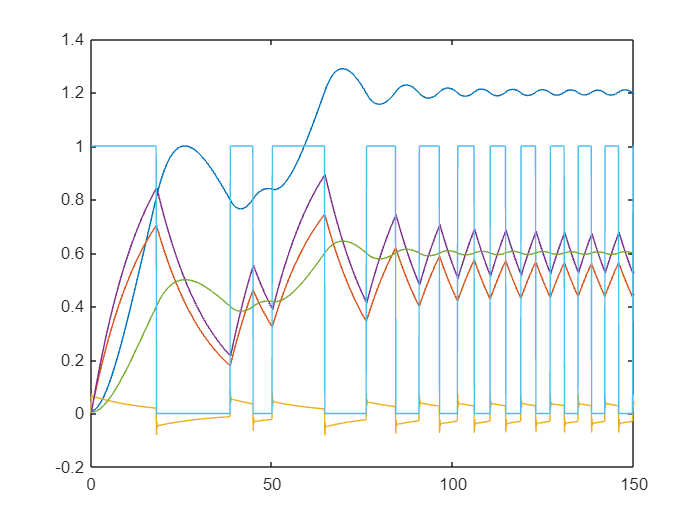

plot(simD.tsim, [simD.x, simD.y, simD.z])

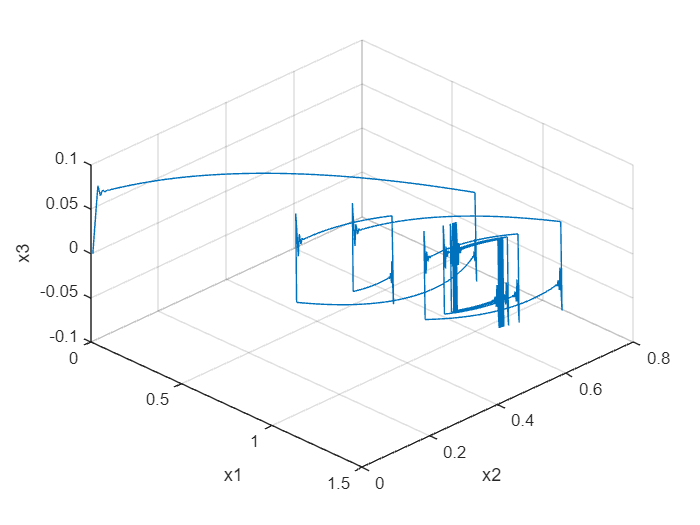

%axis([0 150 -0.5 2])
plot3(simD.x(:,1), simD.x(:,2), simD.x(:,3))
hold on
xlabel('x1')
ylabel('x2') 
zlabel('x3')
grid on
view([45 45])
hold off

## Comparing Simulation Times

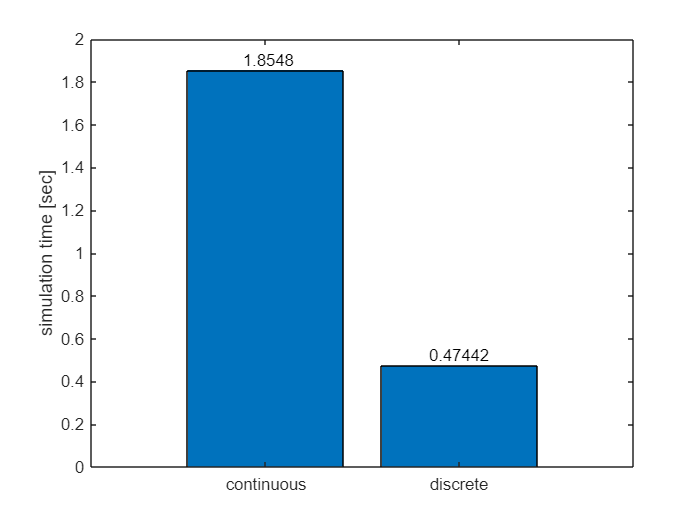

times = [timeC, timeD];
categories = categorical({'continuous', 'discrete'});
categories = reordercats(categories,{'continuous', 'discrete'});
bar(categories, times)
hold on
text(1:length(times),times,num2str(times'),'vert','bottom','horiz','center');
ylabel('simulation time [sec]')
hold off

## Test d2c

sysC = sysD.d2c();

System reduced algebraicly by 3 algebraic variable(s) and 3 equation(s).


sysCEq = sysC.symbolicEquations();
disp(sysCEq)

$$\left(\begin{array}{c} {\mathrm{xp}}_{1}-0.1300\,u_{1}\,x_{2}+0.1300\,u_{2}\,x_{1}=0\\ {\mathrm{xp}}_{2}-x_{3}=0\\ 0.0667\,x_{2}+x_{3}+0.0667\,{\mathrm{xp}}_{3}-0.0667\,z_{1}=0\\ y_{1}-u_{1}\,x_{2}=0\\ y_{2}-u_{2}\,x_{1}=0\\ x_{1}\,\left(2\,z_{1}-1\right)-u_{3}\,\left(2\,z_{1}-1\right)\leq 0 \end{array}\right)$$

ut = 0:150;
x0 = [0.01; 0; 0];
u = [1.2, 0.5, 0.8] .* ones(size(ut))';
u(ut>50,3) = u(ut>50,3) + 0.4;

simC = dmsim(sysC, x0, ut, u);


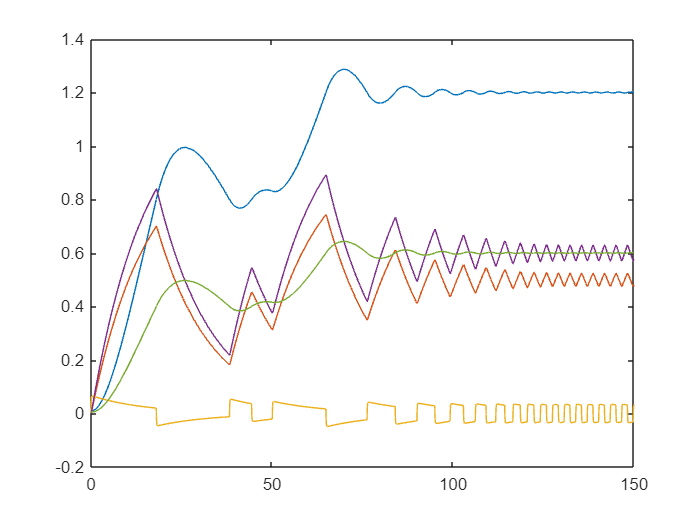

plot(simC.tsim, [simC.x, simC.y])

## Test d2d

ts2 = 0.02;
sysD2 = sysD.d2d(ts2);

System reduced algebraicly by 3 algebraic variable(s) and 3 equation(s).


sysD2Eq = sysD2.symbolicEquations();
disp(sysD2Eq)

$$\left(\begin{array}{c} {\mathrm{xp}}_{1}-x_{1}-0.0026\,u_{1}\,x_{2}+0.0026\,u_{2}\,x_{1}=0\\ {\mathrm{xp}}_{2}-0.0200\,x_{3}-x_{2}=0\\ 0.0200\,x_{2}-0.7000\,x_{3}+{\mathrm{xp}}_{3}-0.0200\,z_{1}=0\\ y_{1}-u_{1}\,x_{2}=0\\ y_{2}-u_{2}\,x_{1}=0\\ x_{1}\,\left(2\,z_{1}-1\right)-u_{3}\,\left(2\,z_{1}-1\right)\leq 0 \end{array}\right)$$

ut = 0:ts2:150;
x0 = [0.01; 0; 0];
u = [1.2, 0.5, 0.8] .* ones(size(ut))';
u(ut>50,3) = u(ut>50,3) + 0.4;

simD2 = dmsim(sysD2, x0, ut, u);


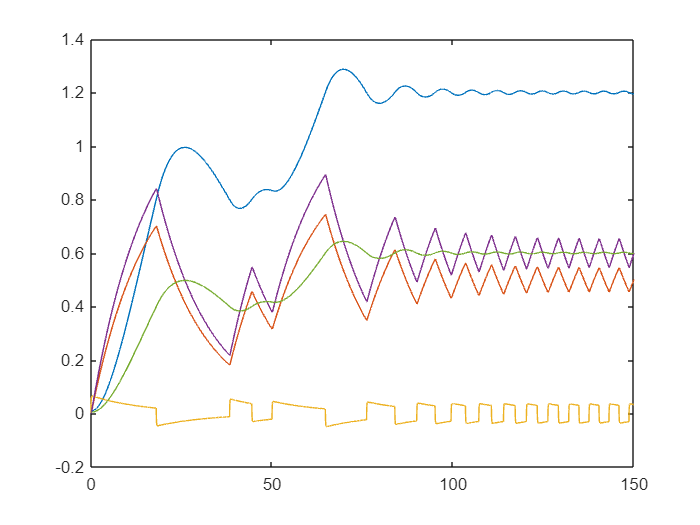

plot(simD2.tsim, [simD2.x, simD2.y])

## Test true-false case (boolean basis, not monomial)

H = hyCPN1();
H.F.state = [];
H.F.stateDerivative = [];
H.F.algebraic = ["true" ""];
H.F.boolean = [];
H.F.input = ["" "true";...
            "" "false"];

H.phi.equality = [1 -1];
H.phi.inequality = [];

boolSys = dmss(H, 0);
boolEq = boolSys.symbolicEquations();
disp(boolEq)

$$y_{1}+u_{1}\,\left(u_{2}-1\right)=0$$

## Test mixed basis

H = hyCPN1();
H.F.state = [];
H.F.stateDerivative = [];
H.F.algebraic = ["true" "0" ""];
H.F.boolean = [];
H.F.input = ["" "true" "";...
            0 "false" "";...
            "" "" 2];

H.phi.equality = ["true" -1 2];
H.phi.inequality = [];

boolSys = dmss(H, 0);
boolEq = boolSys.symbolicEquations();
disp(boolEq)

$$4\,u_{3}+y_{1}+u_{1}\,\left(u_{2}-1\right)-2=0$$


xp = [];
x = [];
y = sym('y', [1,1]);
u = sym('u',[3,1]);
z = [];

% y = 0.1;
% u = [0.5; 0.2; -0.3];

J = boolSys.jacobian(xp, x, u, y, z);
disp([J.equality.stateDerivative, J.equality.state, J.equality.algebraic, J.equality.input, J.equality.boolean])

$$\left(\begin{array}{cccc} 4 & 1 & u_{2}-1 & u_{1} \end{array}\right)$$

## Append and Connect-functions

plantEq = ["xp1 - 0.13*u1*u2 + 0.13*x1*u3 = 0";...
    "y1 - u1*u2 = 0";...
    "y2 - u3*x1 = 0"];
controllerEq = ["xp1 - x2 = 0";...
    "xp2 + x1 + 15*x2 - z1 = 0";...
    "(u1 - u2) * (2*z1 - 1) <= 0"];

plantSys = sym2dmss(plantEq, 0);

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


plantSys.stateName = "fluidlevel";
plantSys.inputName = ["available flow rate", "entry valve position", "exit valve position"];
plantSys.algebraicName = ["entry flow rate", "exit flow rate"];
plantSys.outputIndex.state = 1;
plantSys.outputIndex.algebraic = [1, 2];
plantSys.symbolicEquations

$$ans = \left(\begin{array}{c} {\mathrm{xp}}_{1}-0.1300\,u_{1}\,u_{2}+0.1300\,u_{3}\,x_{1}=0\\ y_{1}-u_{1}\,u_{2}=0\\ y_{2}-u_{3}\,x_{1}=0 \end{array}\right)$$


controllerSys = sym2dmss(controllerEq, 0);

Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.


controllerSys.stateName = ["entry valve position", "filter signal"]; 
controllerSys.inputName = ["fluidlevel", "desired level"];
controllerSys.booleanName = "logic signal";
controllerSys.outputIndex.boolean = 1;
controllerSys.symbolicEquations

$$ans = \left(\begin{array}{c} {\mathrm{xp}}_{1}-x_{2}=0\\ x_{1}+15\,x_{2}+{\mathrm{xp}}_{2}-z_{1}=0\\ u_{2}-u_{1}+2\,u_{1}\,z_{1}-2\,u_{2}\,z_{1}\leq 0 \end{array}\right)$$

## Append-Function:

appendedSys = append(plantSys, controllerSys)

appendedSys =   dmss with properties:

                H: [1×1 hyCPN1]
                n: 3
                m: 5
                p: 2
      outputIndex: [1×1 struct]
              nEq: 5
        stateName: ["fluidlevel"    "entry valve position"    "filter signal"]
        stateUnit: [""    ""    ""]
    algebraicName: ["entry flow rate"    "exit flow rate"]
    algebraicUnit: [""    ""]
        inputName: ["available flow rate"    "entry valve position"    "exit valve position"    "fluidlevel"    "desired level"]
        inputUnit: [""    ""    ""    ""    ""]
               ts: 0


appendedSys.symbolicEquations

$$ans = \left(\begin{array}{c} {\mathrm{xp}}_{1}-0.1300\,u_{1}\,u_{2}+0.1300\,u_{3}\,x_{1}=0\\ y_{1}-u_{1}\,u_{2}=0\\ y_{2}-u_{3}\,x_{1}=0\\ {\mathrm{xp}}_{2}-x_{3}=0\\ x_{2}+15\,x_{3}+{\mathrm{xp}}_{3}-z_{1}=0\\ u_{5}-u_{4}+2\,u_{4}\,z_{1}-2\,u_{5}\,z_{1}\leq 0 \end{array}\right)$$

## **Connect-function (of an appended system via variable names)**

internally connection index matrices are formed from the variable names, and at the end always the connectionByIndices function is used 

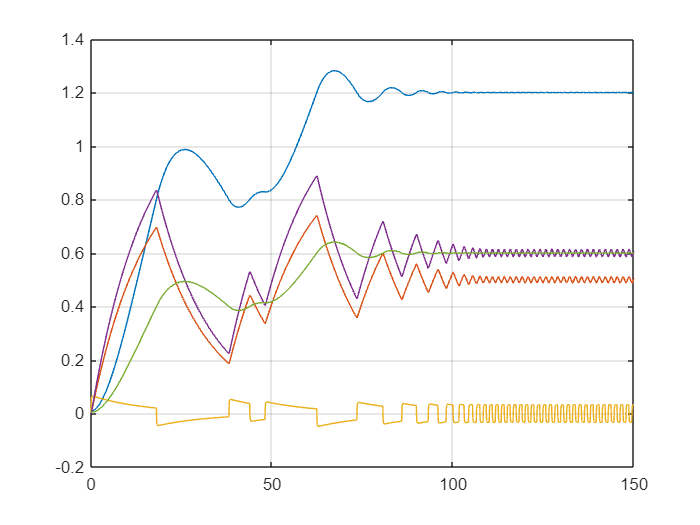

closedLoopSys = appendedSys.connect();
% closedLoopSys.symbolicEquations

ut = 0:150;
x0 = [0.01; 0; 0];
u = [1.2, 0.5, 0.8] .* ones(size(ut))';
u(50:end,3) = u(50:end,3) + 0.4;

closedLoopSim = dmsim(closedLoopSys, x0, ut, u, opt);

plot(closedLoopSim.tsim, [closedLoopSim.x, closedLoopSim.y])
grid on

## Connect-function (without explicitly appending the two systems before hand)

internally the systems will be appended and connected via their variable names (multiple systems can be connected at once)

clear closedLoopSys closedLoopSim
closedLoopSys = connect(plantSys, controllerSys);
% closedLoopSys.symbolicEquations

closedLoopSim = dmsim(closedLoopSys, x0, ut, u, opt);

plot(closedLoopSim.tsim, [closedLoopSim.x, closedLoopSim.y])
grid on

## Connect-Function via indices

clear closedLoopSys closedLoopSim appendedSys plantSys controllerSys

plantSys = sym2dmss(plantEq, 0);

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


controllerSys = sym2dmss(controllerEq, 0);

Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.



appendedSys = append(plantSys, controllerSys);

stateConnections = [2, 2; 4, 1] ;
algebraicConnections = [];
booleanConnections = [];
similarInputs = [];

closedLoopSys = appendedSys.connect(stateConnections, algebraicConnections, booleanConnections, similarInputs);
% closedLoopSys.symbolicEquations

closedLoopSim = dmsim(closedLoopSys, x0, ut, u, opt);
plot(closedLoopSim.tsim, [closedLoopSim.x, closedLoopSim.y])
grid on

## Normalize / Scale

closedLoopSysD = closedLoopSys.c2d(0.1);

System reduced algebraicly by 3 algebraic variable(s) and 3 equation(s).



stateCurrentRange = [0 1.5; 0 1; -0.2 0.2];
stateTargetRange = [-1 1; -1 1; -1 1];
algebraicCurrentRange = [0 1; 0 1];
algebraicTargetRange = [-1 1; -1 1];

[closedLoopSysNorm, xOffset, xSlope, ~,~, yOffset, ySlope ]= closedLoopSysD.normalize(stateCurrentRange, stateTargetRange, [], [], algebraicCurrentRange, algebraicTargetRange);

%opt = odeset('RelTol',1e-6,'AbsTol', 1e-9, 'MaxStep', 1); %, 'MaxStep', 3600/2); %('RelTol',1e-5,'AbsTol', 1e-6);
%method = 'linear';

ut = 0:closedLoopSysNorm.ts:150;
x0 = [0.01; 0; 0];
u = [1.2, 0.5, 0.8] .* ones(size(ut))';
u(ut>50,3) = u(ut>50,3) + 0.4;
x0n = (x0 - xOffset')./xSlope';

tic
normSim = dmsim(closedLoopSysNorm, x0n, ut, u);%, opt, method);
toc()

Elapsed time is 0.419465 seconds.


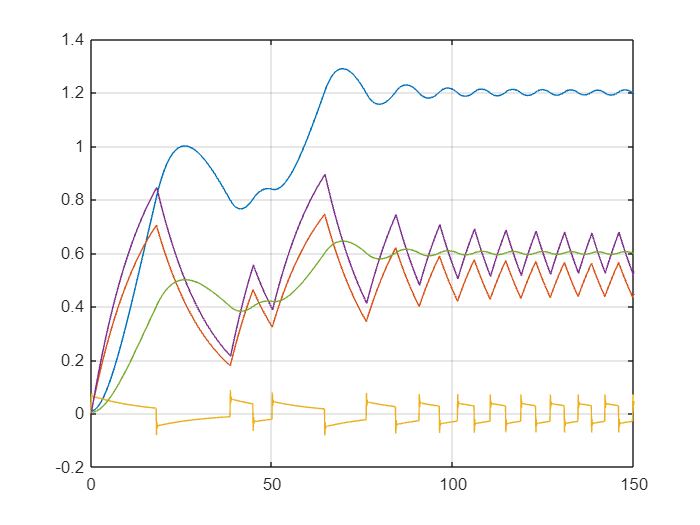


xSim = normSim.x .* xSlope + xOffset;
ySim = normSim.y .* ySlope + yOffset;

tSim = normSim.tsim;

plot(tSim, [xSim, ySim])
grid on

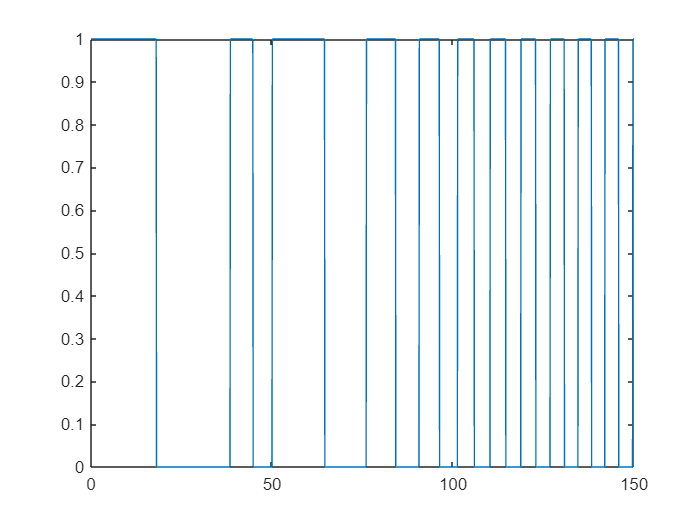

plot(normSim.zt, normSim.z)